# Woche 11 GUI (graphical user interface = grafische Benutzeroberfläche)

## 11.1 Slider

Zum Einstieg programmieren wir eine sehr simplen Slider. Wir schreiben 

`x = ` 

in eine Code-Zelle und klicken dann oben im Menü auf Control und wählen `numeric slider` aus.

x = -70

x = -70

Danach benutzen wir die Variable x, die durch den numerischen Slider befüllt wird, in einer Anweisung und verändern den Slider:

fprintf('Das Quadrat von %g ist %g', x, x^2);

Das Quadrat von -70 ist 4900

Schauen wir uns ein zweites Beispiel an. Wir visualisieren eine Parabel mit einem Vorfaktor, also $f\left(x\right)=a\cdot x^2$. Dazu schreiben wir eine Funktion, die den Vorfaktor als Input-Argument entgegen nimmt und dann die Parabel mit dem Definitionsgebiet [−10,10] zeichnet. Die Implementierung dieser Funktion `zeichne_parabel()` finden Sie ganz unten.

a = 5

a = 5

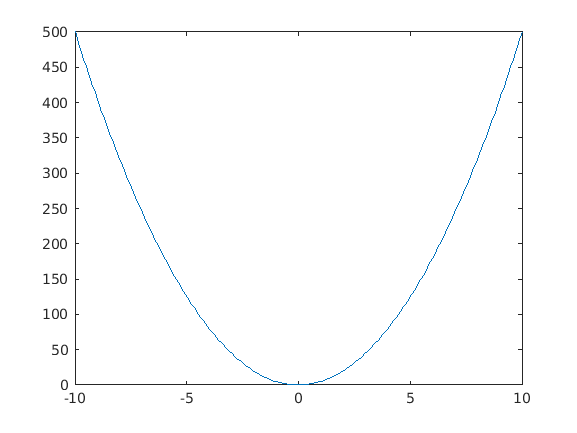

zeichne_parabel(a);

Wie Sie sehen, werden die Optionen für den Slider beim Aufruf gesetzt. Das vertiefen wir gleich. Zunächst eine kleine Aufgabe.

#### Aufgabe 11.1

Schreiben Sie eine Funktion, die die Funktion $f\left(x\right)=\sin \left(k\cdot \;x\right)$ im Intervall $[-2\pi, 2\pi]$ zeichnet. Definieren Sie anschließend für `k` einen Slider. Bewegen Sie anschließend den Slider.

k = 0.2

k = 0.2000

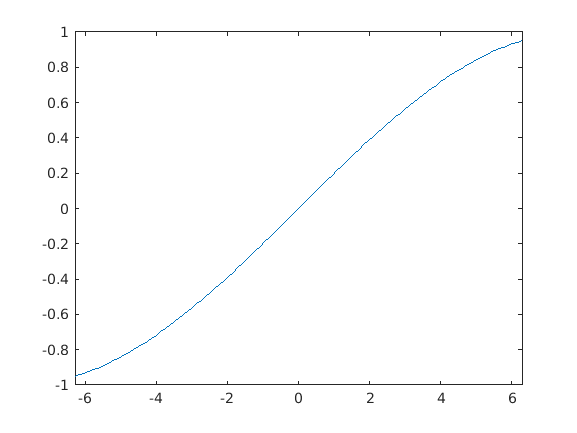

aufgabe_11_01(k)

Es ist auch möglich, zwei Slider zu definieren. Die Funktion `zeiche_punkt()` (Implementierung ganz unten) zeichnet einen Punkt an den Koordinaten (𝑥,𝑦):

x = -2

x = -2

y = 7

y = 7

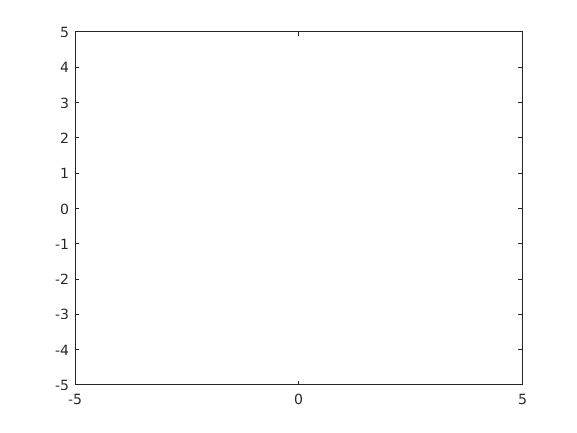


zeichne_punkt(x,y)

#### Aufgabe 11.2

Eine Gerade wird durch die Funktionsgleichung


$$y=m\cdot x + b$$


mit der Steigung $m$ und dem y-Achsenabschnitt $b$ beschrieben. Schreiben Sie eine Funktion, die eine Gerade im Intervall $[-5,5]$ zeichnet und bei der die y-Achse stets zwischen $-10$ und $10$ anzeigt. Eine Benutzerin oder ein Benutzer soll die Steigung im Bereich $m\in[-3,3]$ mit der Schrittweite $0.1$ und den y-Achsenabschnitt $b\in[-7.5, 7.5]$ mit der Schrittweite $0.5$ wählen können. 

m = 1

m = 1

b = -3

b = -3

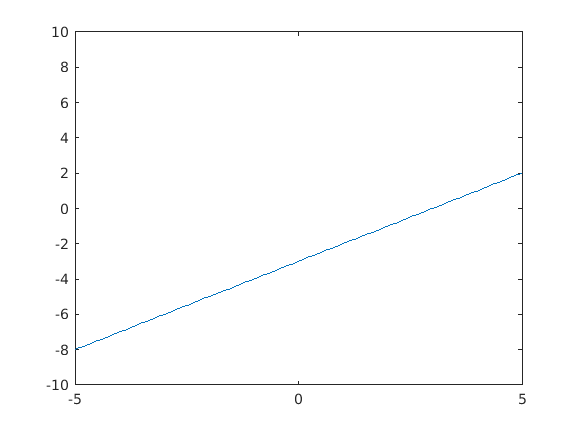

aufgabe_11_02(m,b);

## 11.2 Edit Field

Bei einem Slider wird indirekt eine Variable mit einem Wert gefüllt, indem der Benutzer oder die Benutzerin der Applikation einen Indikator regelt. Im Gegenzug dazu erfolgt die direkte Eingabe über dein sogenanntes **Edit Field**. 

Wir konstruieren ein Eingabefeld für eine Altersabfrage. 

alter = 18

alter = 18

#### Aufgabe 11.3

Schreiben Sie ein Programm, das das Geburtsjahr eines Benutzers über ein Edit Field abfragt und danch das Alter berechnet und ausgibt.

geburtsjahr = 81

geburtsjahr = 81

fprintf('Sie sind %g Jahre alt.', geburtsjahr)

Sie sind 81 Jahre alt.

## 11.3 Drop-Down-Liste

Eine **Drop-Down-Liste**, manchmal auch **Pulldown-Menü** genannt, ermöglicht eine Auswahl aus einer Liste von Objekten. Die einzelnen Auswahlmöglichkeiten werden als Item Labels gelistet. 

x = 2

x = 2

fprintf('Das Quadrat von %g ist %g.', x, x^2);

Das Quadrat von 2 ist 4.

#### Aufgabe 11.4

Schreiben Sie ein Programm, bei dem der Benutzer über zwei Drop-Down-Listen den Tag und den Monat seines Geburtstages auswählt. Lassen Sie den Computer danach feststellen, ob der Benutzer dieses Jahr schon Geburtstag hatte, heute gerade Gebutstag hat (Gratulation) oder noch Geburtstag haben wird. Geben Sie eine entsprechende Meldung aus.

tag = 25

tag = 25

monat = 6

monat = 6

heutiger_tag = 25

heutiger_tag = 25

heutiger_monat = 6

heutiger_monat = 6

if monat < heutiger_monat
    disp('Sie hatten schon Geburtstag.');
elseif monat == heutiger_monat
    if tag < heutiger_tag
        disp('Sie hatten schon Geburtstag.');
    elseif tag == heutiger_tag
        disp('Happy Birthday :-)');
    else
        disp('Sie werden dieses Jahr noch Geburtstag haben...');
    end
else
    disp('Sie werden dieses Jahr noch Geburtstag haben...');
end

Happy Birthday :-)


## 11.4 Checkbox

Checkboxen sind explizit für die Abfrage von booleschen Werte, d.h. wahr oder falsch, gemacht. Hier direkt ein Beispiel:

w = false

w = logical
   0


disp(w)

   0



Wir erweitern unseren Plot der Sinus-Funktion um eine Legende.

w = true

w = logical
   1


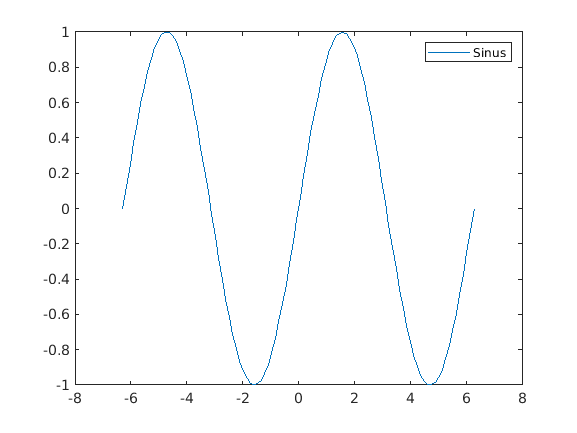

plotte_sinus(w);

#### Aufgabe 11.5

Schreiben Sie ein Programm, bei dem der Benutzer über eine Drop-Down-Liste zwischen den Funktionen Sinus und Kosinus wählen darf. Anschließend wird die ausgewählte Funktion im Intervall [−2𝜋,2𝜋] gezeichnet. Über eine Checkbox darf der Benutzer entscheiden, ob die Gitterlinien eingeblendet werden sollen oder nicht.

% Optionenwahl
funktion_dropdown = "Sinus"

funktion_dropdown = "Sinus"

mit_gitter = true

mit_gitter = logical
   1


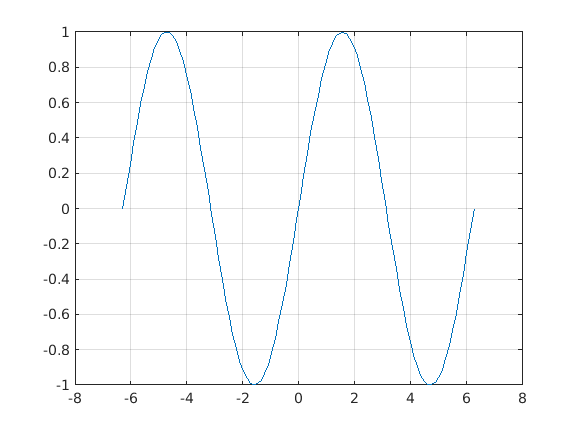


% Programm
x = linspace(-2*pi, 2*pi);
if funktion_dropdown == "Sinus"
    y = sin(x);
else
    y = cos(x);
end
plot(x,y);
if mit_gitter == true
    grid on;
end

function zeichne_parabel(a)
    x = linspace(-10, 10, 200);
    y = a .* x.^2;
    plot(x,y);
end

function zeichne_punkt(x,y)
    plot(x,y, 'o')
    xlim([-5,5])
    ylim([-5,5])
end

function plotte_sinus(mit_legende)
    x = linspace(-2*pi, +2*pi);
    y = sin(x);
    plot(x, y)
    if mit_legende == true
        legend('Sinus')
    end
end
        
function aufgabe_11_01(k)
    x = linspace(-2*pi, 2*pi);
    y = sin(k*x);
    plot(x,y);
    xlim([-2*pi, 2*pi]);
    ylim([-1,1]);
end

function aufgabe_11_02(m,b)
    x = linspace(-5, 5);
    y = m.*x + b;
    plot(x,y);
    xlim([-5,5]);
    ylim([-10,10])
end